# Transducer Design

Transducer 1

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;        % 40kHz (operating frequency of transducer)
% transducer_info.Pressure = 36.3477;   % Surface outcome pressure [Pa]
transducer_info.Pressure = 1;  
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.medium = 'air';

% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:8
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
% phases = PFC_PhaseCalculate_for16([0.04, 0.04], [8,8], 0.2)
phases = PFC_PhaseCalculate([0.02, 0.12], [8,8], 0.2)

phases =     4.4191    7.9731   11.2709   14.2965   17.0346   19.4698   21.5879   23.3755
    4.7392    8.3000   11.6043   14.6363   17.3802   19.8209   21.9438   23.7356
    4.7392    8.3000   11.6043   14.6363   17.3802   19.8209   21.9438   23.7356
    4.4191    7.9731   11.2709   14.2965   17.0346   19.4698   21.5879   23.3755
    3.7808    7.3214   10.6060   13.6193   16.3457   18.7702   20.8787   22.6579
    2.8279    6.3484    9.6138   12.6087   15.3178   17.7265   19.8209   21.5879
    1.5654    5.0598    8.3000   11.2709   13.9576   16.3457   18.4215   20.1727
         0    3.4626    6.6721    9.6138   12.2732   14.6363   16.6898   18.4215


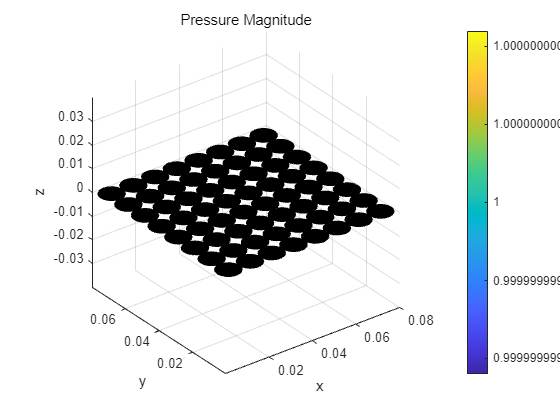

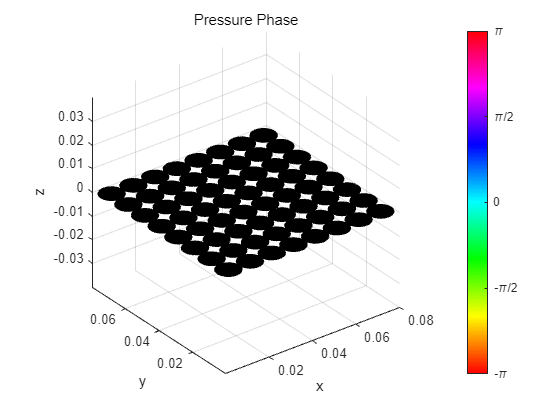

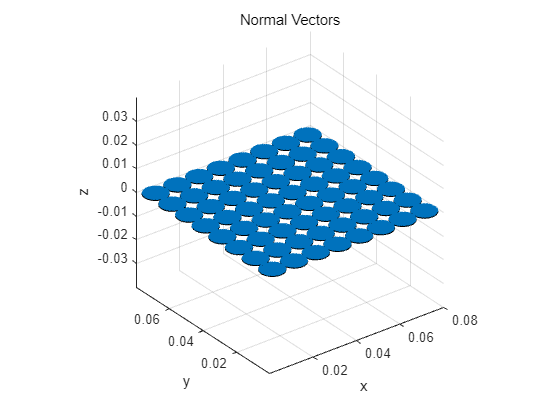


% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:8
    for j = 1:8
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];

        % transducer_info.Phase = phases(i,j);
        transducer_info.Phase = phases(i,j);
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = -80e-3 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_y = -80e-3 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_z = 0e-3 : 0.5e-3 : 800e-3;          % Simulation Area

## Run Frequency Domain Simulation

XZ Plane

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.125, reading_pos_z);

Started at 2024-07-29 22:55:47
Finished at 2024-07-29 23:05:15
Progressed time : 00:09:28


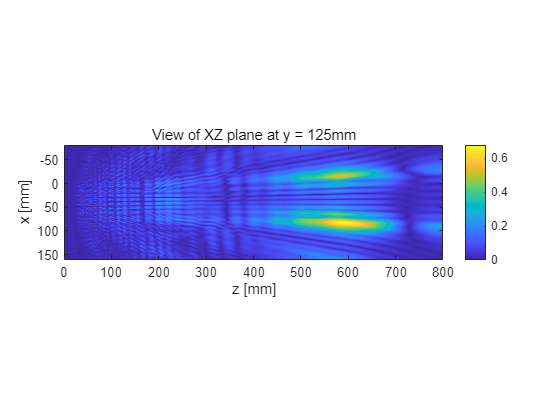


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 125mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');

M1 = max(Pressure_dxyz_i,[],"all")

M1 = 0.6798

XY Plane

% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.2);

Started at 2024-07-29 23:05:16
Finished at 2024-07-29 23:08:06
Progressed time : 00:02:50


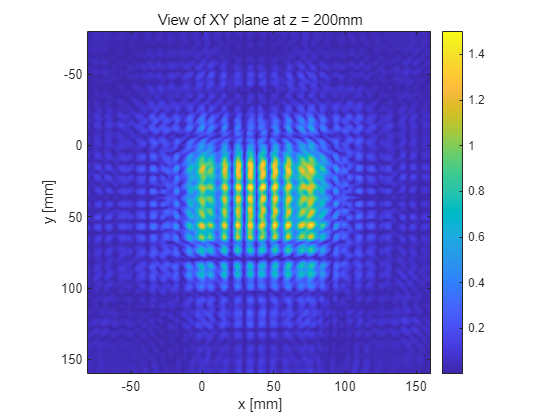


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 200mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');

M2 = max(Pressure_dxyz_i,[],"all")

M2 = 1.5025